##                                                             Robótica - Cinemática Direta

##                                                                       Lista 05 - Parte 2

clear; clc;
import RoboticaBiblioteca.*

maoDireita()

--- Regra da mão Direita ---
     eixo x --- indicador
     eixo y --- meio
     eixo z --- dedão
----------------------------
ver palma da mão -> positivo
para z: < positivo | > negativo
para x: palma da mão pra cima - positivo | palma da mão pra baixo - negativo
para y: pistola pra baixo - positivo | pistola pra cima - negativo


**Exercício 6)** Consider the two-link cartesian manipulator. Derive the forward kinematic equations using the DH-convention.

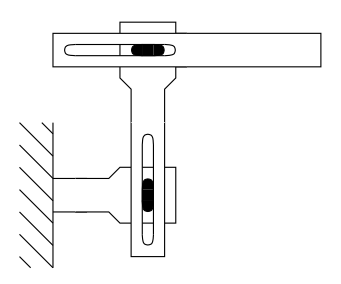

|  link  |  a  | alpha |   d  |  theta  |

| 0 - 1 |  0  |     0    |  l1* |   -90    |  P

| 1 - 2 |  0  |     0    |  l2* |     0     |  P

syms l1 l2;
DH = [0 -90 l1 0;
      0 0 l2 0];
usarDenavit()

denavit(theta, d, a, alpha)


A02 = MatProgDenavit(DH)

A01 = 


$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & \cos\left(90\right) & \sin\left(90\right) & 0\\ 0 & -\sin\left(90\right) & \cos\left(90\right) & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A12 = 


$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & l_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$A02 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & \cos\left(90\right) & \sin\left(90\right) & l_{2}\,\sin\left(90\right)\\ 0 & -\sin\left(90\right) & \cos\left(90\right) & l_{1}+l_{2}\,\cos\left(90\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

**REVER!!**

**Exercício 7)** Consider the two-link manipulator which has joint 1 revolute and joint 2 prismatic. Derive the forward kinematic equations using the DH-convention.

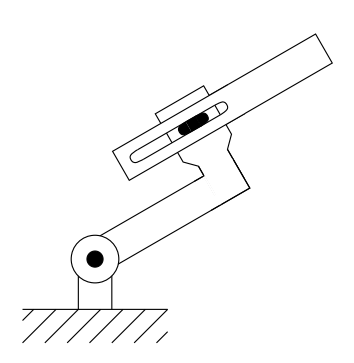

|  link  |  a  | alpha |   d  |  theta  |

| 0 - 1 |    |     +90    |  d1 |  0  |  P

| 1 - 2 |  a2  |     0    |  l2* |     theta1*     |  P

**REVER!!**

**Exercício 8)** Consider the three-link planar manipulator. Derive the forward kinematic equations using the DH-convention.

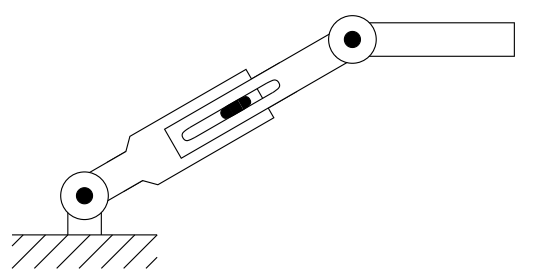

|  link  |   a  | alpha |   d  |   theta   |

| 0 - 1 |   0  |  +90   |  0   |  theta1* |  R

| 1 - 2 |   0  |   -90   |  l2* |       0     |  P

| 2 - 3 |  a3 |     0    |  0   |  theta3* |  R

syms theta1 l2 theta3;
syms a3;
DH = [0 +90 0 theta1;
      0 -90 l2 0;
      a3 0 0 theta3];
A03 = MatProgDenavit(DH)

A01 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\cos\left(90\right)\,\sin\left(\theta_{1}\right) & \sin\left(90\right)\,\sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & \cos\left(90\right)\,\cos\left(\theta_{1}\right) & -\sin\left(90\right)\,\cos\left(\theta_{1}\right) & 0\\ 0 & \sin\left(90\right) & \cos\left(90\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A12 = 


$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & \cos\left(90\right) & \sin\left(90\right) & 0\\ 0 & -\sin\left(90\right) & \cos\left(90\right) & l_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A23 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & a_{3}\,\cos\left(\theta_{3}\right)\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & a_{3}\,\sin\left(\theta_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$A03 = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)-\sin\left(\theta_{3}\right)\,\sigma_{1} & -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{3}\right)\,\sigma_{1} & 0 & l_{2}\,\sin\left(90\right)\,\sin\left(\theta_{1}\right)-a_{3}\,\sin\left(\theta_{3}\right)\,\sigma_{1}+a_{3}\,\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)\\ \cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)+\sin\left(\theta_{3}\right)\,\sigma_{2} & \cos\left(\theta_{3}\right)\,\sigma_{2}-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right) & 0 & a_{3}\,\sin\left(\theta_{3}\right)\,\sigma_{2}-l_{2}\,\sin\left(90\right)\,\cos\left(\theta_{1}\right)+a_{3}\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\\ 0 & 0 & {\cos\left(90\right)}^{2}+{\sin\left(90\right)}^{2} & l_{2}\,\cos\left(90\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\cos\left(90\right)}^{2}\,\sin\left(\theta_{1}\right)+{\sin\left(90\right)}^{2}\,\sin\left(\theta_{1}\right)\\ \sigma_{2}={\sin\left(90\right)}^{2}\,\cos\left(\theta_{1}\right)+{\cos\left(90\right)}^{2}\,\cos\left(\theta_{1}\right) \end{array}$$

% Compute simplified symbolic expression
simplifiedExpr3 = simplify(A03)

$$simplifiedExpr3 = \left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{3}\right) & -\sin\left(\theta_{1}+\theta_{3}\right) & 0 & \frac{l_{2}\,\cos\left(\theta_{1}-90\right)}{2}-\frac{l_{2}\,\cos\left(\theta_{1}+90\right)}{2}+a_{3}\,\cos\left(\theta_{1}+\theta_{3}\right)\\ \sin\left(\theta_{1}+\theta_{3}\right) & \cos\left(\theta_{1}+\theta_{3}\right) & 0 & \frac{l_{2}\,\sin\left(\theta_{1}-90\right)}{2}-\frac{l_{2}\,\sin\left(\theta_{1}+90\right)}{2}+a_{3}\,\sin\left(\theta_{1}+\theta_{3}\right)\\ 0 & 0 & 1 & l_{2}\,\cos\left(90\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

**Exercício 9)** Consider the three-link articulated robot. Derive the forward kinematic equations using the DH-convention.

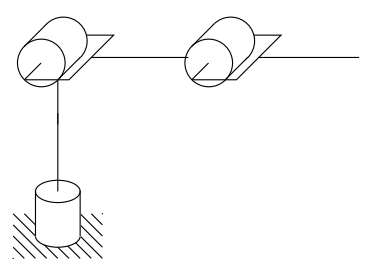

|  link  |   a  | alpha |   d  |   theta   |

| 0 - 1 |   0  |  +90   |  l1  |  theta1* |  R

| 1 - 2 |  l2  |     0    |   0  |  theta2* |  R

| 2 - 3 |  l3  |     0    |   0  |  theta3* |  R

syms theta1 theta2 theta3;
syms l1 l2 l3;
DH = [0 +90 l1 theta1;
      l2 0 0 theta2;
      l3 0 0 theta3];
A03 = MatProgDenavit(DH)

A01 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\cos\left(90\right)\,\sin\left(\theta_{1}\right) & \sin\left(90\right)\,\sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & \cos\left(90\right)\,\cos\left(\theta_{1}\right) & -\sin\left(90\right)\,\cos\left(\theta_{1}\right) & 0\\ 0 & \sin\left(90\right) & \cos\left(90\right) & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A12 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & l_{2}\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & l_{2}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A23 = 


$$\left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & l_{3}\,\cos\left(\theta_{3}\right)\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & l_{3}\,\sin\left(\theta_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% Compute simplified symbolic expression
simplifiedExpr = simplify(A03)

**Exercício 10)** Consider the three-link cartesian manipulator. Derive the forward kinematic equations using the DH-convention.

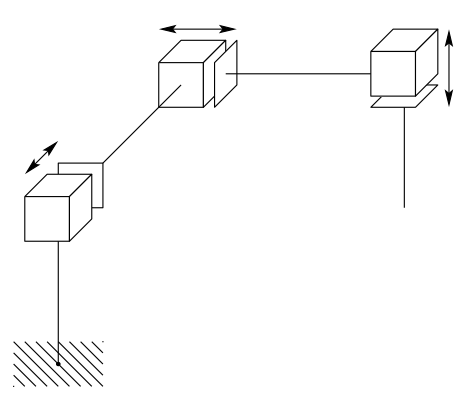

|  link  |   a  | alpha |   d  |   theta   |

| 0 - 1 |   0  |   -90   |  l1* |       0     |  P

| 1 - 2 |   0  |  +90   |  l2* |   +90     |  P

| 2 - 3 |   0  |     0    |  l3* |        0    |  R

syms l1 l2 l3;
DH = [0 -90 l1 0;
      0 +90 l2 +90;
      0 0 l3 0];
A03 = MatProgDenavit(DH)

A01 = 


$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & \cos\left(90\right) & \sin\left(90\right) & 0\\ 0 & -\sin\left(90\right) & \cos\left(90\right) & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A12 = 


$$\left(\begin{array}{cccc} \cos\left(90\right) & -\cos\left(90\right)\,\sin\left(90\right) & {\sin\left(90\right)}^{2} & 0\\ \sin\left(90\right) & {\cos\left(90\right)}^{2} & -\cos\left(90\right)\,\sin\left(90\right) & 0\\ 0 & \sin\left(90\right) & \cos\left(90\right) & l_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A23 = 


$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & l_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$A03 = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(90\right) & -\sigma_{3} & {\sin\left(90\right)}^{2} & l_{3}\,{\sin\left(90\right)}^{2}\\ \sigma_{3} & {\cos\left(90\right)}^{3}+{\sin\left(90\right)}^{2} & \sigma_{2} & l_{2}\,\sin\left(90\right)+l_{3}\,\sigma_{2}\\ -{\sin\left(90\right)}^{2} & \sigma_{2} & \sigma_{1} & l_{1}+l_{2}\,\cos\left(90\right)+l_{3}\,\sigma_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(90\right)\,{\sin\left(90\right)}^{2}+{\cos\left(90\right)}^{2}\\ \sigma_{2}=\sigma_{3}-{\cos\left(90\right)}^{2}\,\sin\left(90\right)\\ \sigma_{3}=\cos\left(90\right)\,\sin\left(90\right) \end{array}$$

% Compute simplified symbolic expression
simplifiedExpr2 = simplify(A03)

$$simplifiedExpr2 = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(90\right) & -\frac{\sin\left(180\right)}{2} & {\sin\left(90\right)}^{2} & l_{3}\,{\sin\left(90\right)}^{2}\\ \frac{\sin\left(180\right)}{2} & {\cos\left(90\right)}^{3}+{\sin\left(90\right)}^{2} & \sigma_{1} & \sin\left(90\right)\,\left(l_{2}+l_{3}\,\cos\left(90\right)-l_{3}\,{\cos\left(90\right)}^{2}\right)\\ -{\sin\left(90\right)}^{2} & \sigma_{1} & \cos\left(90\right)\,\left(\cos\left(90\right)+{\sin\left(90\right)}^{2}\right) & l_{1}+l_{2}\,\cos\left(90\right)+l_{3}\,\left(\cos\left(90\right)\,{\sin\left(90\right)}^{2}+{\cos\left(90\right)}^{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sin\left(180\right)}{2}-\frac{\sin\left(90\right)}{4}-\frac{\sin\left(270\right)}{4} \end{array}$$